# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 5: Kmeans (Unsupervised Learning)

Nota: Se necesita tener instalada la Toolbox: "statistics and Machine Learning"

El objetivo de este ejercicio es hacer **agrupamiento** con **k-means **utilizando la base de datos  `fisheriris.mat`, que es un conjunto de datos de clasificación multiclase muy sencillo. Introducido por el estadístico y biólogo británico Ronald Fisher en su artículo de 1936. Contine 150 muestras, 50 muestras para cada una de las tres especies de flores Iris {`setosa, versicolor y virginica`}. Cada muestra contiene 4 características de las flores en el siguiente orden: 

- Longitud del sépalo.

- Anchura del sépalo.

- Longitud del pétalo.

- Anchura del pétalo

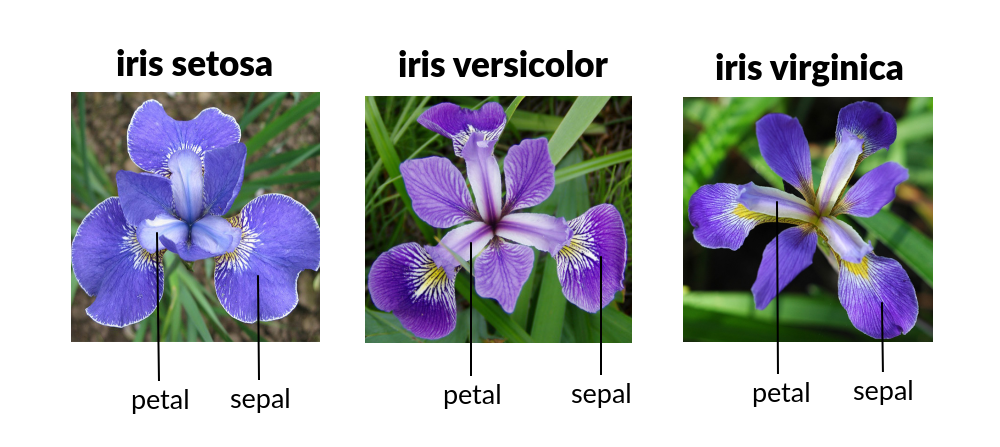

Los pasos que se deben realizar son:

- Cargar sólo la longitud y anchura del sépalo base de datos 

- Visualizar los datos

- Realizar el agrupamiento con el algoritmo k-Means.

- Visualizar el resultado del clustering.

Se pide:

    Primera parte

- Complete la variable llamada `C_init` y guarda en ella los valores iniciales de los 3 centroides calculados comose indica en el siguiente pseudocódigo: `C_init(1)= [min(longitud sépalo), min(anchura sépalo)], C_init(1)= [mean(longitud sépalo), mean(anchura sépalo)]` y `C_init(3)= [max(longitud sépalo), max(anchura sépalo)]`. Utilice  las funciones que calculan el mínimo ([min](https://es.mathworks.com/help/matlab/ref/min.html?searchHighlight=min&s_tid=srchtitle_support_results_1_min)), la media ([mean](https://es.mathworks.com/help/matlab/ref/mean.html?searchHighlight=mean&s_tid=srchtitle_support_results_1_mean)) y el máximo ([max](https://es.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle_support_results_1_max)).

- Ejecute el código y explique los resultados que obtiene el algoritmo k-means en cada iteración. ¿qué representa `iter`, `num`  y `sum`?.

    Segunda parte

    Hay que tener en cuenta que este es un algoritmo no supervisado por lo que los índices de salida (**idx**) no se corresponden con los nombres de las flores. Sin embargo, si queremos saber cómo de bien ha realizado el algorimto k-Means el agrupamiento debemos relacionar cada cluster con su etiqueta correspondiente. Sabemos que los datos de entrada (`data_iris`) están ordenados siguiendo la siguiente distribución: los primero 50 datos son '`setosa`', los 50 siguientes son '`versicolor`' y los últimos 50 son '`virginica`'. Para asignar cada índice con su correspondiente etiqueta se va a suponer que el clasificador k-means ha hecho un buen trabajo y el valor que más se repite (la moda) entre los primeros 50 datos es 'setosa', en los siguientes 50 datos es'versicolor' y en los últimos 50 es'virginica'.

- Calcule la moda con la función [mode](https://es.mathworks.com/help/matlab/ref/mode.html?searchHighlight=mode&s_tid=srchtitle_support_results_1_mode) de los 50 primeros índices y guardelo en la variable `setosa_idx`.

- Calcule la moda con la función [mode](https://es.mathworks.com/help/matlab/ref/mode.html?searchHighlight=mode&s_tid=srchtitle_support_results_1_mode) de los siguientes 50 índices y guardelo en la variable `versicolor_idx`.

- Calcule la moda con la función [mode](https://es.mathworks.com/help/matlab/ref/mode.html?searchHighlight=mode&s_tid=srchtitle_support_results_1_mode) de los 50 últimos índices y guardelo en la variable `virginica_idx`.

- Calcule la matriz de confusión del algoritmo K-means usando la función [confusionmat](https://es.mathworks.com/help/stats/confusionmat.html?searchHighlight=confusionmat&s_tid=srchtitle_support_results_1_confusionmat) y guarde el valor en la variable `CM_kmeans`. 

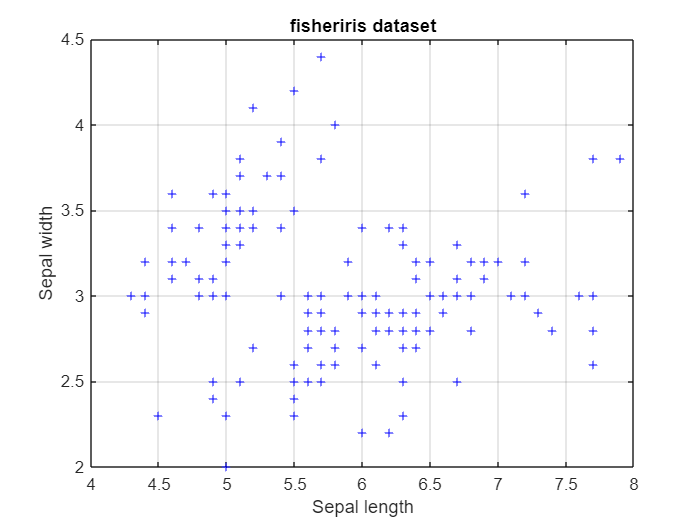

clear all;
close all;

%% ===== Primera Parte =====
% --- (1) ---
% carga las siguientes variables:
% meas: contiene los valores de las 150 muestras en el siguiente orden:
%       [longitud sépalo, anchura sépalo, longitud pétalo, anchura pétalo] 
% species: en un cell array con las 150etiquetas de cada especie {setosa}, {versicolor} o {virginica}
load fisheriris

% carga  [longitud sépalo, anchura sépalo]
data_iris = meas(:,1:2);
% covierte el array en 'categorical'
label_iris = categorical(species);
% cell array que contienen las etiquetas de las 3 categorías
names_iris = categories(label_iris);

% --- (2) ---
% visualiza los datos
figure(1)
plot(data_iris(:,1),data_iris(:,2),'b+','MarkerSize',5);
xlabel('Sepal length');
ylabel('Sepal width');
title('fisheriris dataset');
grid;


% --- (3) ---
% Custering
 
k = 3; % clusters

%% --- COMPLETAR AQUÍ!!! ---
C_init = [min(data_iris(:,1)), min(data_iris(:,2)); 
    mean(data_iris(:,1)), mean(data_iris(:,2)); 
    max(data_iris(:,1)), max(data_iris(:,2))];

%  'Start', C_init: toma los centroides de C_init
%   'MaxIter', 100: número máximo de iteraciones
% 'Display','iter': muestra los valores intermedios

% idx: indices de pertenencia a los k clusters
%   C: centroides de los k clusters
[idx, C] = kmeans(data_iris, k, 'Start', C_init, 'MaxIter', 100, 'Display', 'iter');

  iter	 phase	     num	         sum
     1	     1	     150	     90.2601
     2	     1	      37	     54.1135
     3	     1	      21	     42.8584
     4	     1	      12	     38.7615
     5	     1	       4	     37.8779
     6	     1	       2	     37.8135
     7	     1	       2	     37.7538
     8	     1	       1	     37.6912
     9	     1	       3	     37.4976
    10	     1	       2	     37.3848
    11	     1	       2	     37.2783
    12	     1	       3	     37.1828
    13	     1	       1	     37.1096
    14	     1	       1	     37.0863
Best total sum of distances = 37.0863


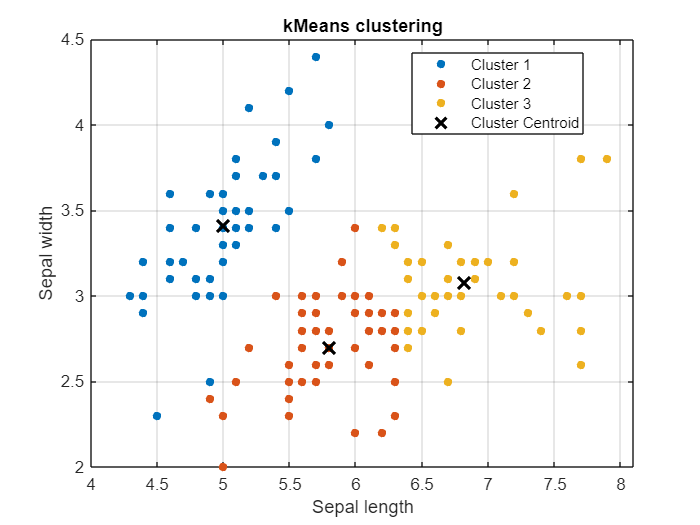


% --- (4) ---
figure(2)
gscatter(data_iris(:,1),data_iris(:,2),idx)
xlabel('Sepal length');
ylabel('Sepal width');
title('kMeans clustering');
hold on;
plot(C(:,1),C(:,2),'kx','MarkerSize',10, 'LineWidth',2)
legend('Cluster 1','Cluster 2','Cluster 3','Cluster Centroid');
hold off
grid;

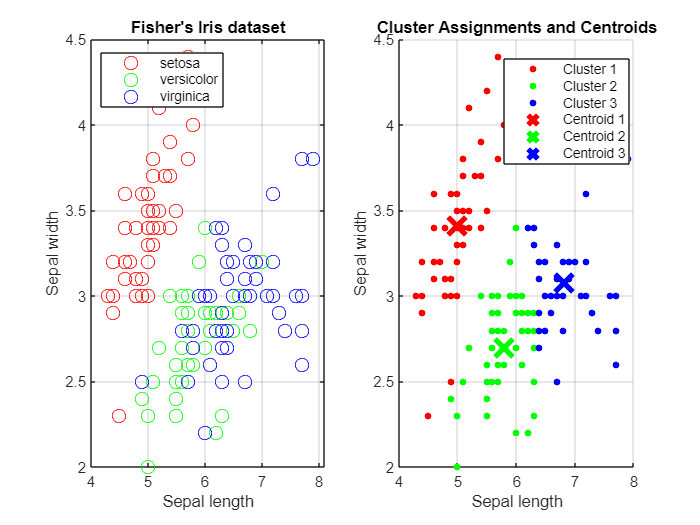


%% ===== Segunda Parte =====

%% --- COMPLETAR AQUÍ!!! ---
setosa_idx = [mode(idx(1:50,:))];
versicolor_idx = [mode(idx(51:100,:))];
virginica_idx = [mode(idx(101:150,:))];

label_kmeans = categorical(idx,[setosa_idx versicolor_idx virginica_idx],{'setosa' 'versicolor' 'virginica'});

% Fisher''s Iris dataset
figure(3);
subplot(1,2,1)
gscatter(data_iris(:,1),data_iris(:,2), label_iris,'rgb','ooo',8,'on')
xlabel('Sepal length');
ylabel('Sepal width');
grid on;
legend('setosa','versicolor', 'virginica' ,'Location','NW')
title ('Fisher''s Iris dataset')

% K-Means clustering
subplot(1,2,2)
hold on
plot(data_iris(idx==setosa_idx,1),data_iris(idx==setosa_idx,2),'r.','MarkerSize',12)
plot(data_iris(idx==versicolor_idx,1),data_iris(idx==versicolor_idx,2),'g.','MarkerSize',12)
plot(data_iris(idx==virginica_idx,1),data_iris(idx==virginica_idx,2),'b.','MarkerSize',12)
plot(C(setosa_idx,1),C(setosa_idx,2),'rx','MarkerSize',15,'LineWidth',3) 
plot(C(versicolor_idx,1),C(versicolor_idx,2),'gx','MarkerSize',15,'LineWidth',3) 
plot(C(virginica_idx,1),C(virginica_idx,2),'bx','MarkerSize',15,'LineWidth',3) 
xlabel('Sepal length');
ylabel('Sepal width');
grid on;

legend('Cluster 1','Cluster 2','Cluster 3','Centroid 1','Centroid 2','Centroid 3','Location','best')
title ('Cluster Assignments and Centroids')
hold off

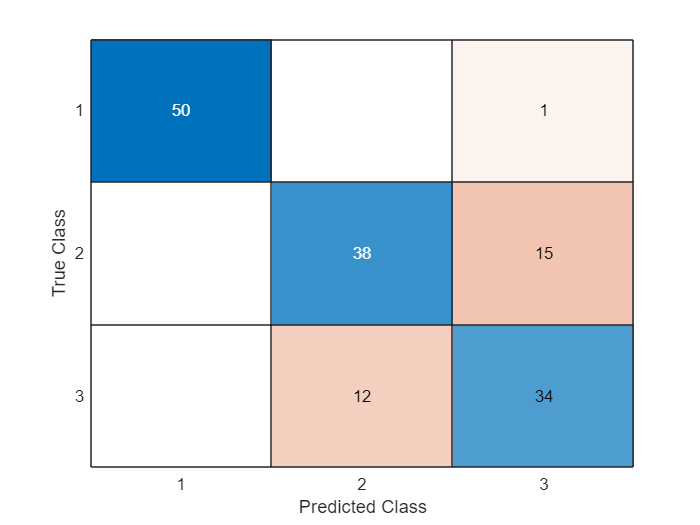


%% --- COMPLETAR AQUÍ!!! ---

target = zeros(150, 1);
target(1:50) = 1;
target(51:100) = 2;
target(101:150) = 3;
CM_kmeans = confusionmat(idx, target);
figure(4)
confusionchart(CM_kmeans);